# Plik zawiera kierunkowość odbicia od struktury to wyniki pomiarów rozpraszacza dźwięku. Struktura (powiedzmy kawałek płyty) leżała płasko na podłodze, nad tym wisiał głośnik (w odległości 4 metrów). Pomiary obejmują wartości SPL dla mikrofonu znajdującego się na łuku o promieniu 2 m, gdzie 0 stopni to jest na wysokości struktury, 90 stopni jest dokładnie na osi łączącej głośnik i strukturę. 

clear variables;
load('angles.dat');
load('freqs.dat');
load('data.dat');

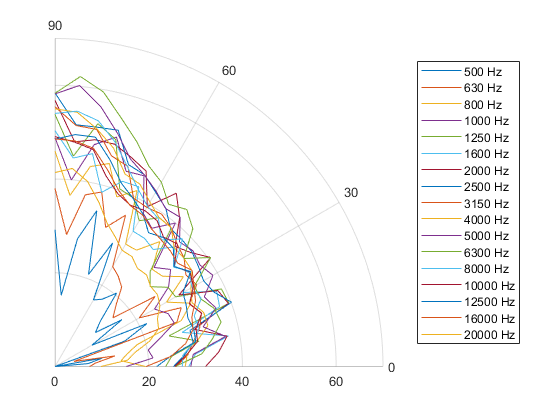

angles_rad = deg2rad(angles);
polarplot(angles_rad, data);
thetalim([ 0 90 ]);
legend(string(freqs) + " Hz")

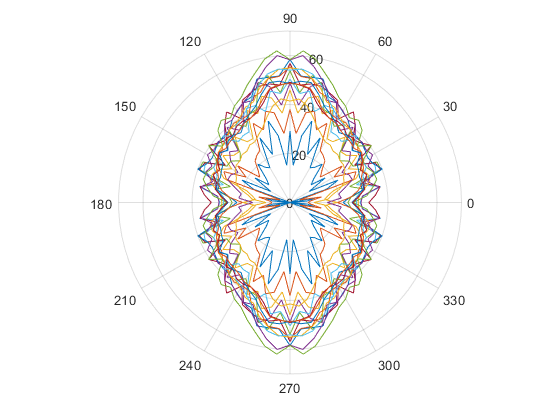

angles2 = [angles; (angles+90); (angles+180); (angles+270)];
angles2_rad = deg2rad(angles2);

polarplot(angles2_rad, [data;flip(data);data;flip(data)])